# Polynomial Regression

We will demonstrate the effect of the degree of the polynomial model on the fit of the data. For high degree, the polynomial is very flexible and can fit the data well, but the polynomial may vary wildly in between data points. For low degree, the polynomial is not very flexible and will be quite smooth. This example illustrates the important concept of *overfitting* in machine learning.

First generate some synthetic data.

fun = @(x) sin(2*pi*x); % true function
sigma2 = 0.1;           % noise variance
n = 10;                 % number of observations
delta = 1/(n+1);        % spacing between observations
x = (delta:delta:1-delta)';
y = fun(x) + sqrt(sigma2)*randn(size(x));

Set up the least squares design matrix for polynomials up to degree 9.

X0 = [ones(n,1) x x.^2 x.^3 x.^4 x.^5 x.^6 x.^7 x.^8 x.^9];

Loop over the polynomial degree and compute and plot the polynomial model.

Degree 1


w =     1.2375
   -2.6423


Reduced chi-squared: 3.144327


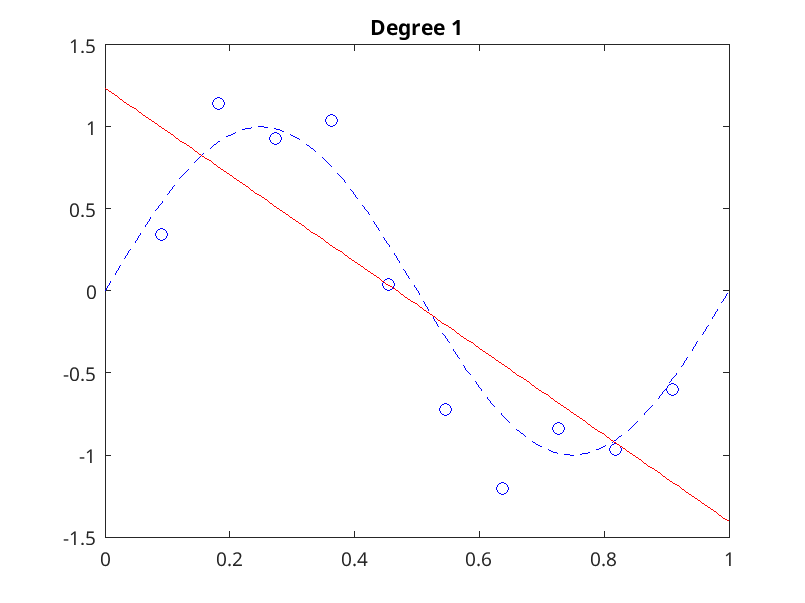

Degree 2


w =     1.4021
   -3.5475
    0.9052


Reduced chi-squared: 3.551302


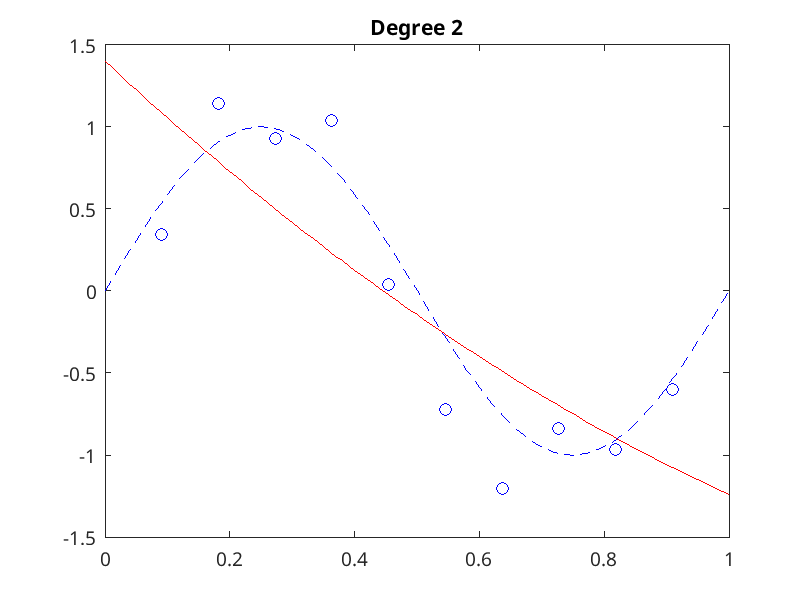

Degree 3


w =    -0.7675
   17.6192
  -49.5779
   33.6554


Reduced chi-squared: 0.851695


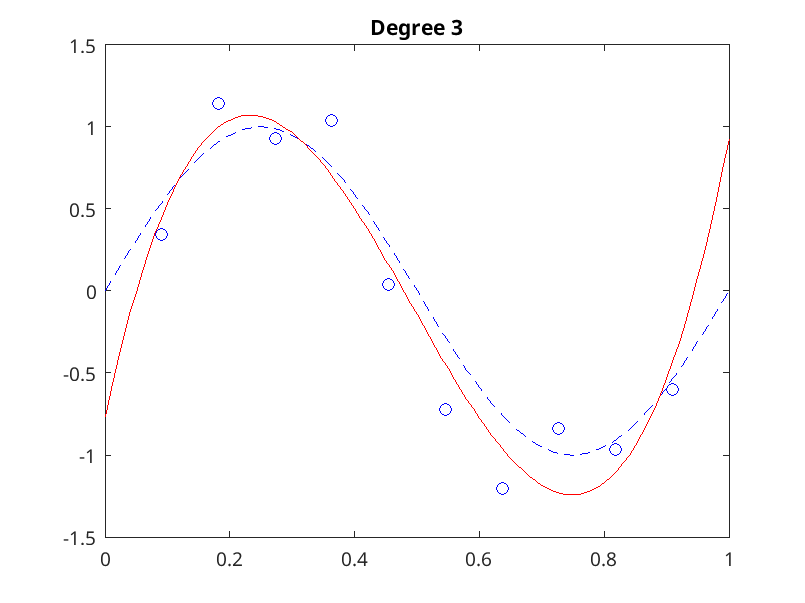

Degree 4


w =    -1.9186
   33.8529
 -114.9184
  131.8691
  -49.1068


Reduced chi-squared: 0.651386


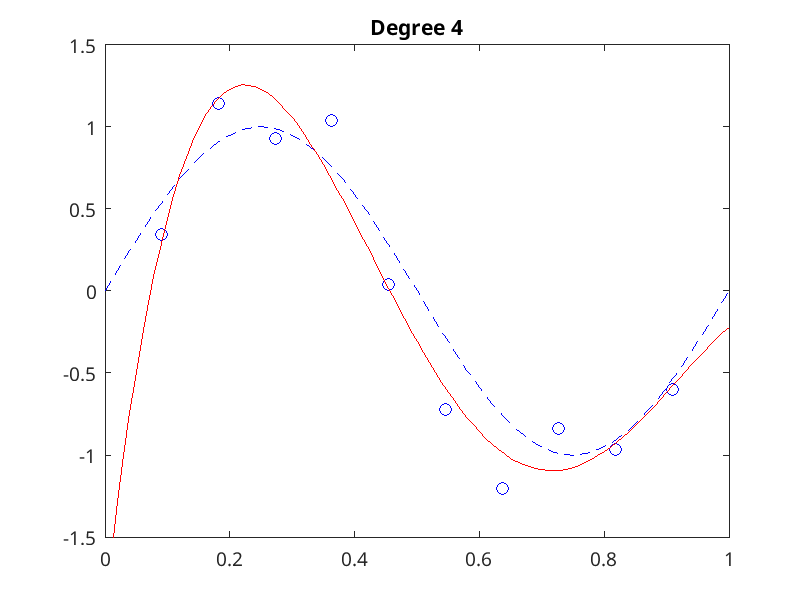

Degree 5


w =    -0.6087
   10.1007
   22.2392
 -205.4371
  319.6948
 -147.5206


Reduced chi-squared: 0.650622


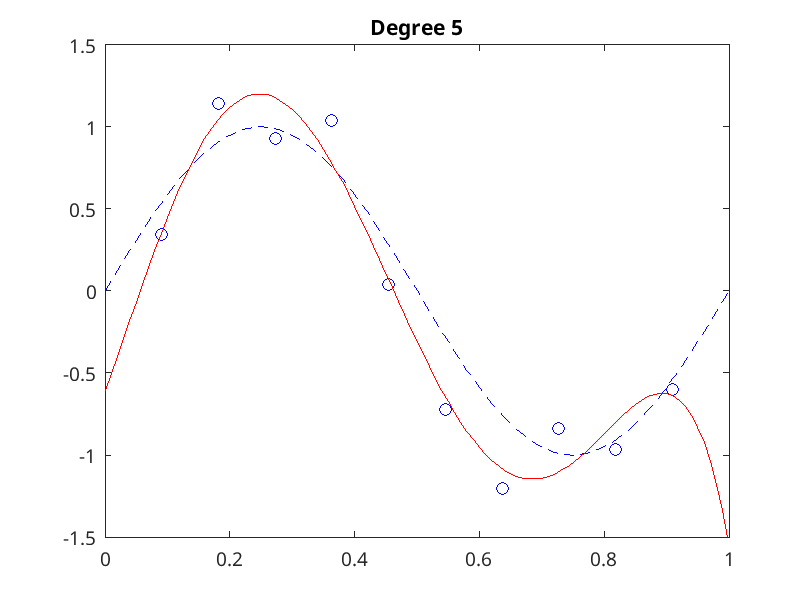

Degree 6


w = 	1.0e+03 *

    0.0005
   -0.0148
    0.2093
   -0.8557
    1.4598
   -1.1255
    0.3260


Reduced chi-squared: 0.832034


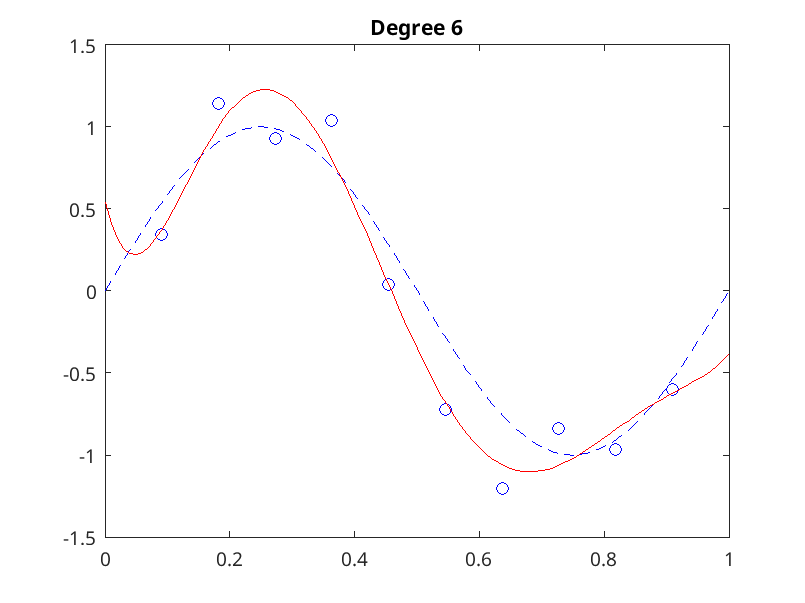

Degree 7


w = 	1.0e+04 *

   -0.0012
    0.0300
   -0.2664
    1.2066
   -3.0175
    4.1779
   -2.9924
    0.8643


Reduced chi-squared: 0.258022


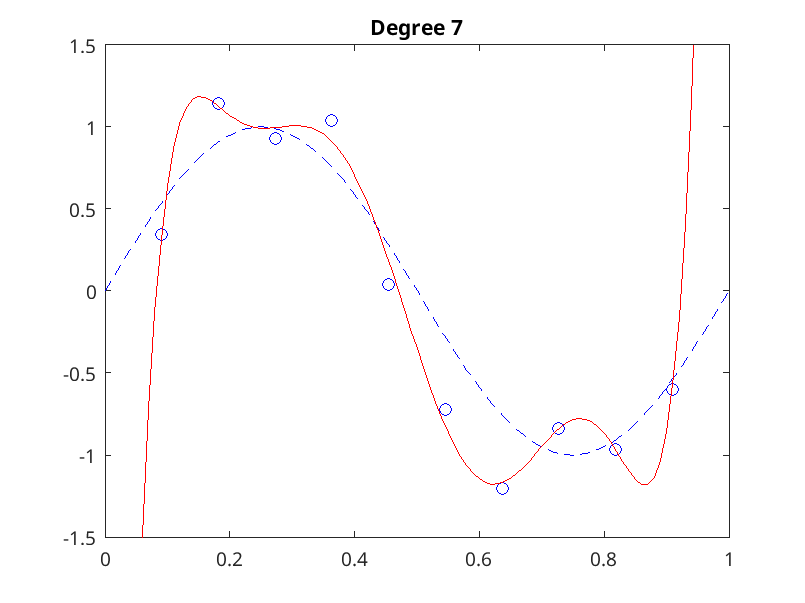

Degree 8


w = 	1.0e+05 *

   -0.0002
    0.0051
   -0.0491
    0.2440
   -0.6899
    1.1458
   -1.1023
    0.5668
   -0.1201


Reduced chi-squared: 0.444692


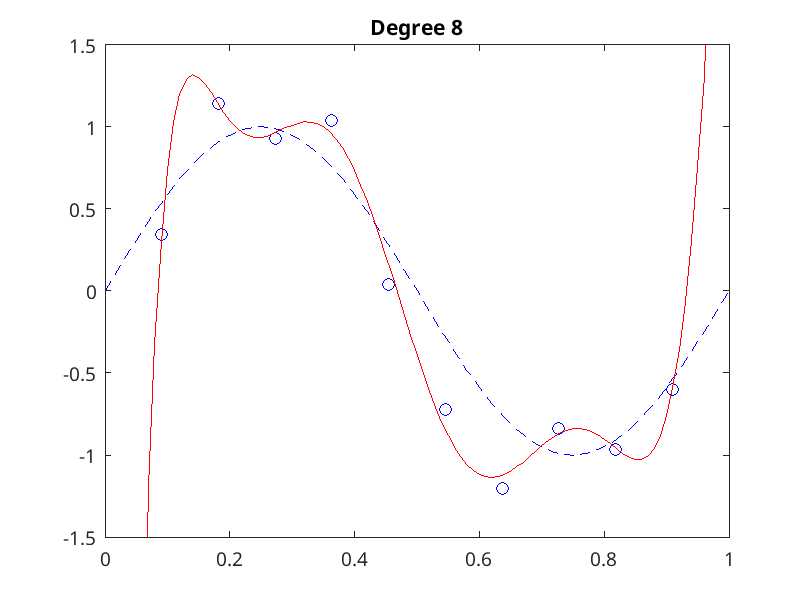

Degree 9


w = 	1.0e+06 *

   -0.0001
    0.0032
   -0.0367
    0.2278
   -0.8470
    1.9792
   -2.9326
    2.6759
   -1.3716
    0.3021


Reduced chi-squared: Inf


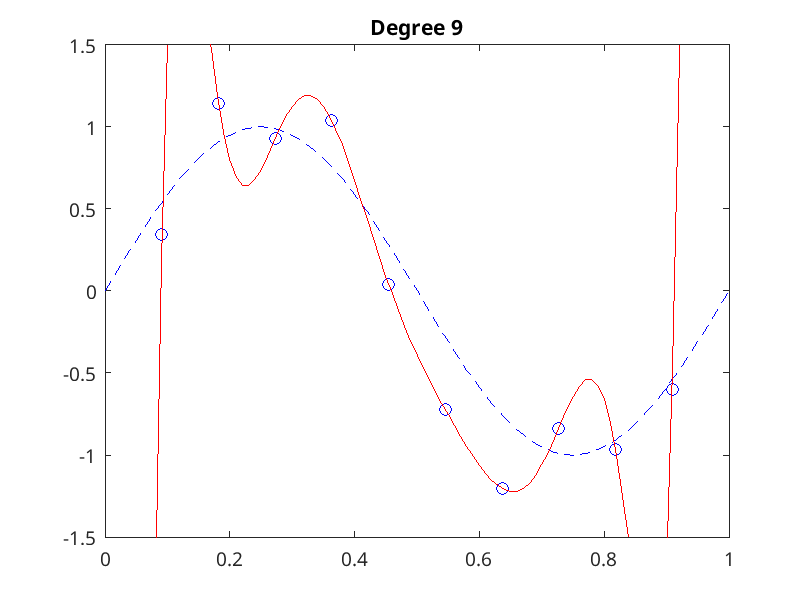

for deg = 1:9
  fprintf('Degree %d\n', deg);
  
  % compute the polynomial weights
  X = X0(:,1:deg+1);
  w = X\y

  % compute the polynomial at values of xx
  xx = (0:.01:1)';
  yy = w(1)*ones(size(xx));
  for k = 1:deg
    yy = yy + w(k+1)*(xx.^k);
  end
  
  % compute RSS and reduced chi-squared statistic
  % first compute predicted values for each x value
  yhat = w(1)*ones(size(x));
  for k = 1:deg
    yhat = yhat + w(k+1)*(x.^k);
  end  
  rss = (y-yhat)'*(y-yhat);
  fprintf('Reduced chi-squared: %f\n', rss/sigma2/(n-deg-1));
  
  % plot the true function, the data, and the polynomial
  figure
  plot(xx,fun(xx),'b--', x,y,'bo', xx,yy,'r-');
  title(sprintf('Degree %d', deg));
  axis([0 1 -1.5 1.5]);
end

What degree polynomial seems to best fit the data?

Polynomial regression is not used in practice, because of the large fluctuations in the polynomial when the polynomial degree increases and the polynomial starts to overfit the data. A sign of overfitting is the very large polynomial weights. We will see later that polynomial regression with regularization (by restraining the weights to be small) can help avoid overfitting the data and will work much better.

### Reduced chi-squared statistic

The code above also computes the reduced chi-squared statistic for the fit. Values much greater than 1 indicate that the fit is poor, and values much less than 1 indicate that we have overfit the data. The reduced chi-squared statistic is not perfect for this problem, and you can try re-running the above script with different data to see how the statistic performs.

### Taking it further

An obvious thing for you to try is to generate some test data and compute the test mean squared error (MSE) for different polynomial degrees. Does the test MSE give you a better indication of what is the best fit for the data? Consider how many test points you need.